close all
clear
clc

定义系统传递函数

a = [1, 7, 10];
b = [1, 6, 4];
sys = tf(b,a);

用step函数绘制系统阶跃响应

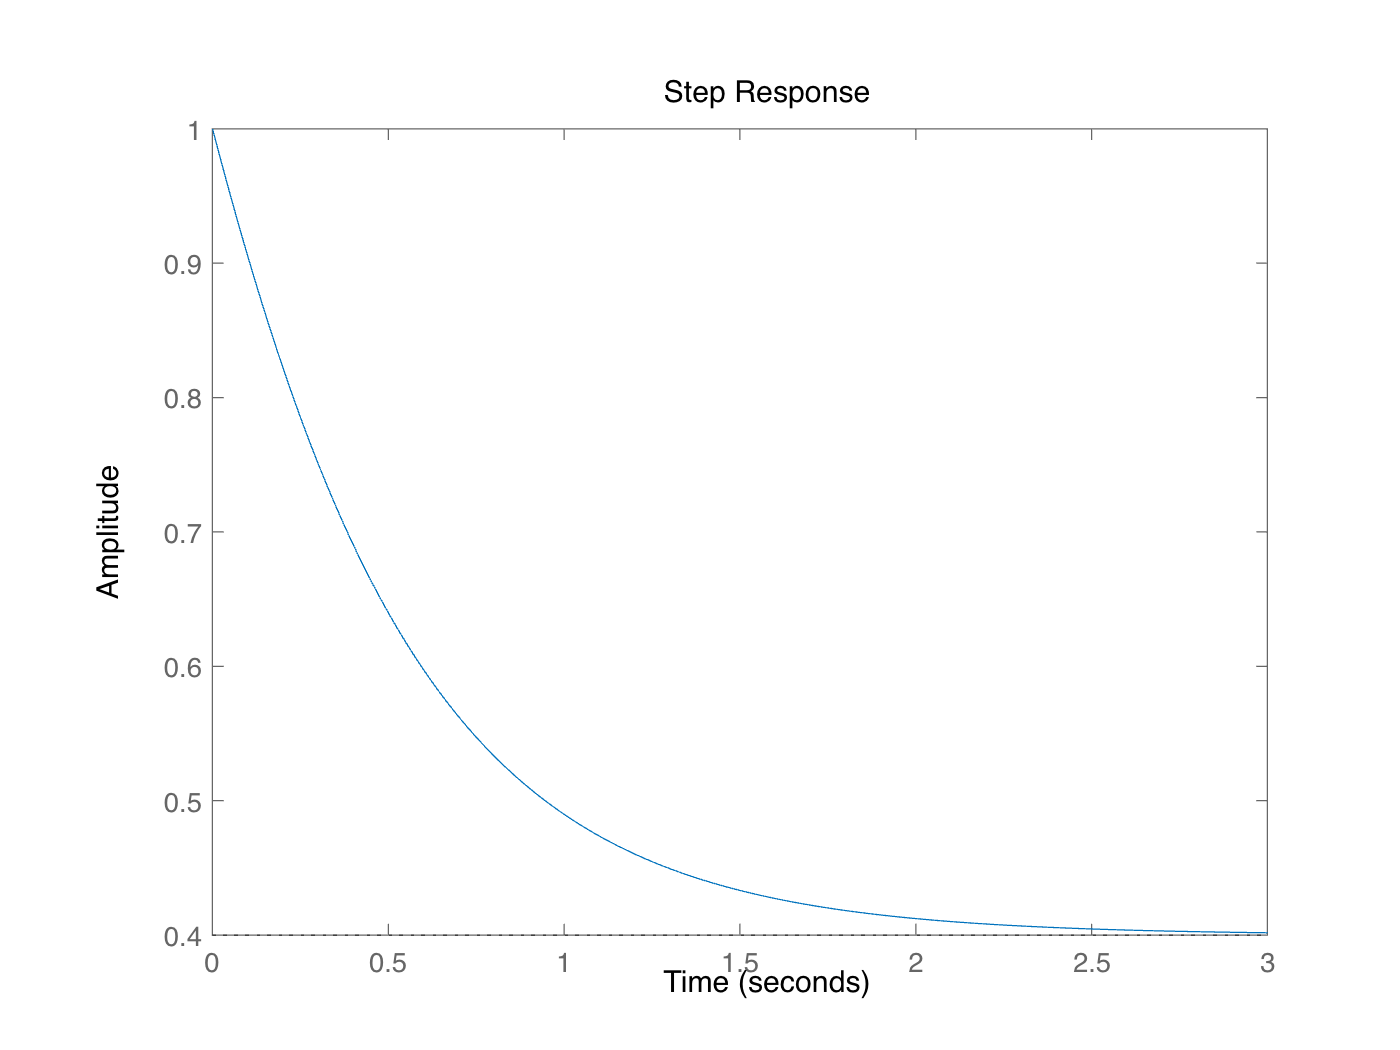

figure;
step(sys);

生成采样时刻，按定义生成阶跃信号，用lsim仿真得到阶跃响应

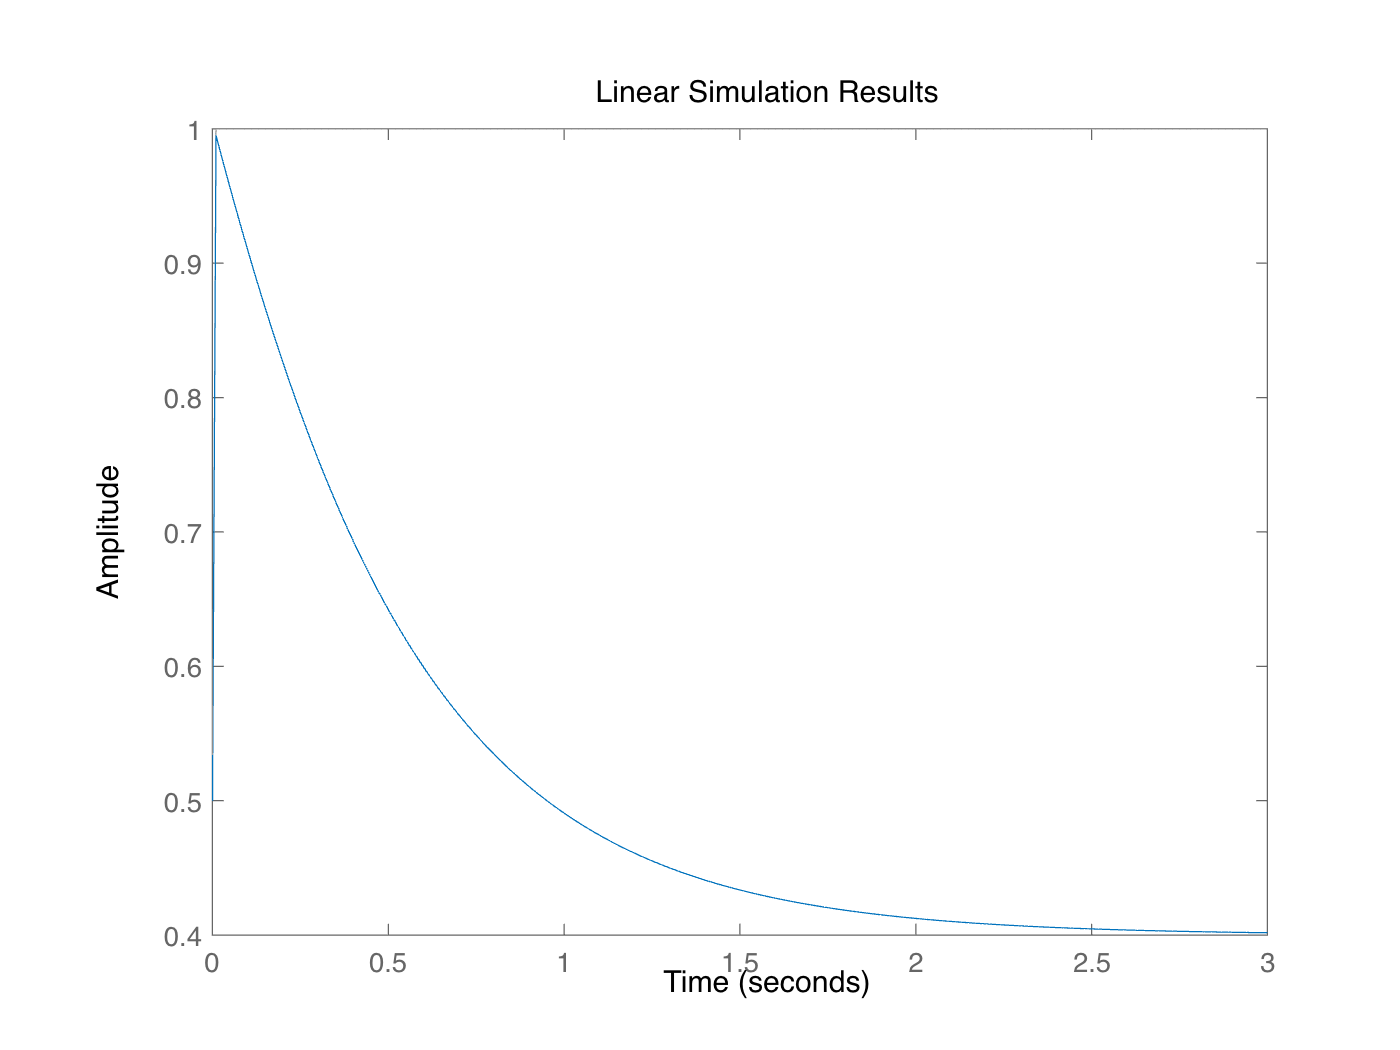

t = [0:0.01:3]';
figure;
x_step = zeros(size(t));
x_step(t>0) = 1;
x_step(t==0) = 1/2;
lsim(sys,x_step,t);

用impulse函数生成冲激响应，绘图

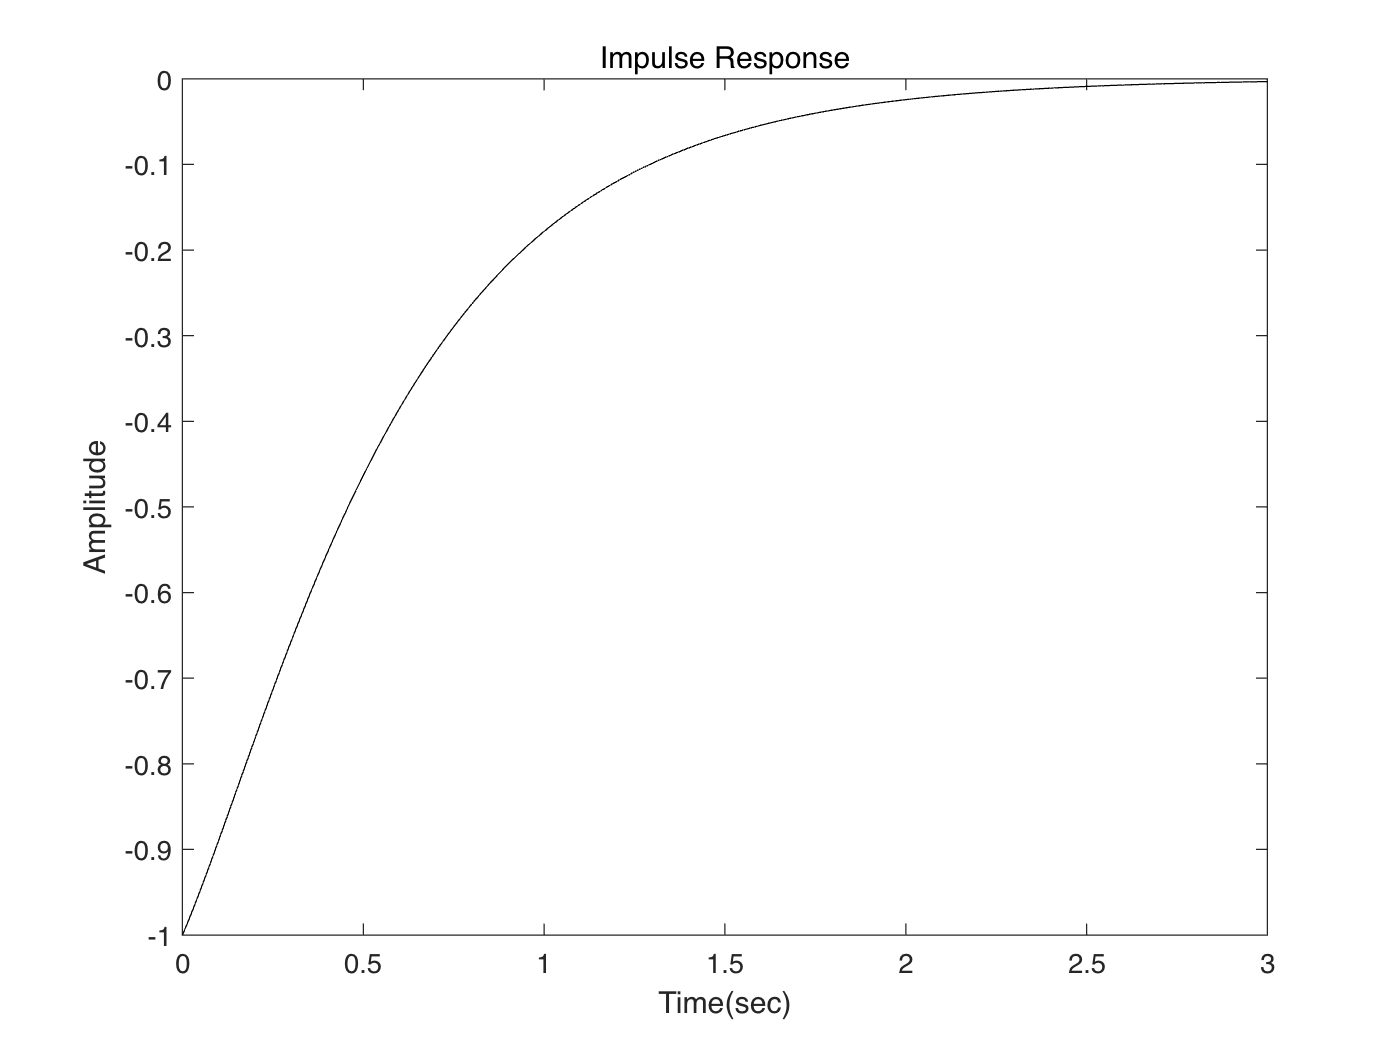

figure;
[h1,t1] = impulse(sys,t);
plot(t1,h1,'k');
title('Impulse Response');
xlabel('Time(sec)');
ylabel('Amplitude');

按定义生成冲激信号，用lsim仿真得到冲激响应，绘图

注意从lsim结果中去掉冲激信号（系统表现为直连，冲激响应里有冲激信号）

对比上下图说明impulse计算的冲激响应是不含冲激信号的

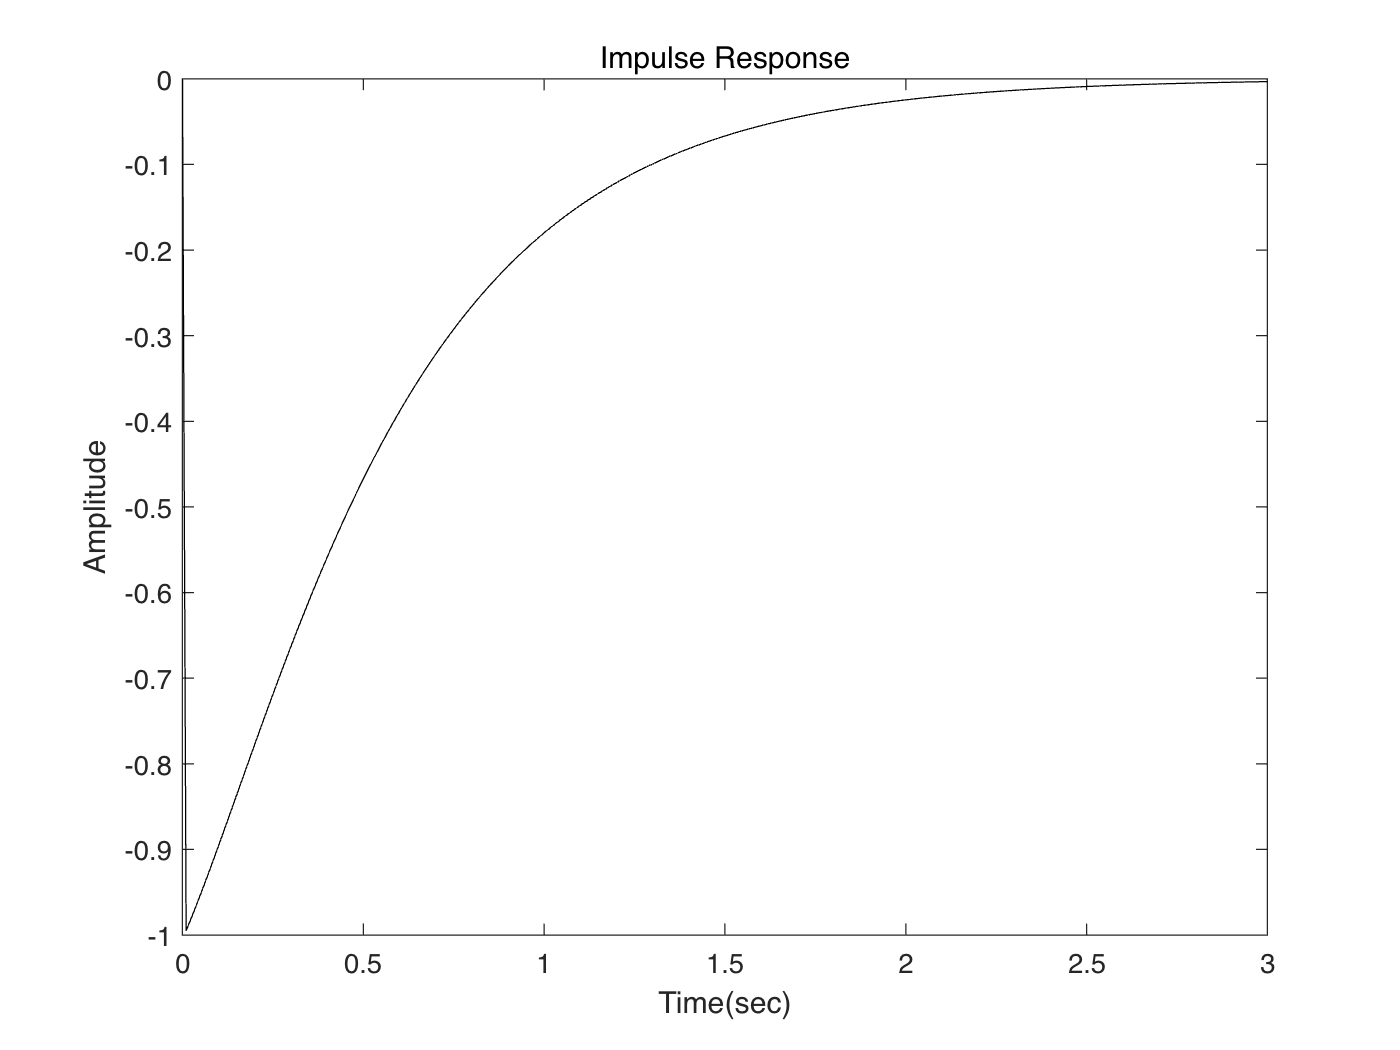

figure;
x_delta = zeros(size(t));
x_delta(t==0) = 100;
[y1,t] = lsim(sys,x_delta,t);
y2 = y1 - x_delta;
plot(t,y2,'k');
title('Impulse Response');
xlabel('Time(sec)');
ylabel('Amplitude');